# Actividad 4.2 (Seguimiento de Trayectorias)

## **Alumnos:**

Jonathan Josafat Vázquez Suárez

Diego Garcia Rueda

Jhonatan Yael Martinez Vargas

- **Implementar** el código requerido para generar el seguimiento de las siguientes trayectorias con un robot tipo diferencial:

El funcionamiento base del codigo es mediante una funcion la cual se encarga de realizar un control proporcional es decir mediante una ganancia, de ajustar el error que percibe el durante la trayectoria cartesiana. Los conceptos usados para la generacion de la trayectoria y del error es el conocimiento del modelo cinematico, usando derivadas de posicion para calcular la velocidad. Para el movimiento del robot, usamos matrices jacovianas para relacionar velocidad lineal y angular del robot, estas velocidades retroalimentadas son ajustadas con un control de ganancia el cual definimos como K, este valor es definido para cada una de las trayectorias de ejemplo mostradas en los siguientes codigos. 

Para cada seguimiento, usamos un inciso definido de trayectoria llamado hxd y hyd. Los parametros que realmente definen el control de trayectoria son nuestro tiempo, este controla cual es el paso y el tiempo total, el paso es primordial ya que aun paso mas grande, el ajuste sera menos suave, pero a un ajuste mas pequeño, podriamos tener osilaciones grandes en velocidades, ambos son un resultado no deseado. El tiempo total define cual sera el fin de la trayectoria y a su vez puede afectar en como es visualizada la trayectoria, para el caso de un circulo, a un tiempo mayor podria solo repetir la vuelta, cosa que no es necesaria para el analisis de resultados. Por ultimo, nuestro ajuste de ganancias, al ser medida junto al error, el tener un valor menor a 1, daria una retroalimentacion que tarda un tiempo infinito en llegar al objetivo, ya que solo estamos reduciedo el error que recibe sin embargo nunca lo alcanzamos, para ciertos tipos de trayectorias este error puede ser ideal, sin embargo no es un parametro comunmente usado para un control proporcional, para el caso de un numero mayor a 1 significa que escala nuestro error para tener un ajuste mas rapido, el ser un numero muy grande puede generar que el movimiento sea mayor al que verdaderamente debe corregir, lo que causa como problemas que en sentidos opuestos (positivo, negativo) deba estar corrigiendo su trayectoria, que en cierto punto puede o no alcanzar su objetivo. 

Trayectorias a generar: 

**    a)** **x =2cos(0.2*t), y = 2sen(0.4*t),**

**    b)** **x =t−3sen(t), y = 4−3cos(t)**

**    c)** **x =3cos(t)−cos(3t), y = 4sin(3t),**

**    d)** **x = cos(t) + 1/2cos(7t) + 1/3sen(17t), y =** **sen****(t) + 1/2sen(7t) + 1/3cos(17t)**

**    e)** **x =17cos(t)+7cos(17+7t), y = 17sen(t) −7sen(17+7t), t ∈ [0,2****π]**

**    f)** **x =2cos(t), y = 2sen(t)**

**    g)** **x =5t−4sen(t), y = 5t−4cos(t)**

**    h)** **x =4cos(t)+cos(4t), y = 4sen(t) −****sen****(4t)**

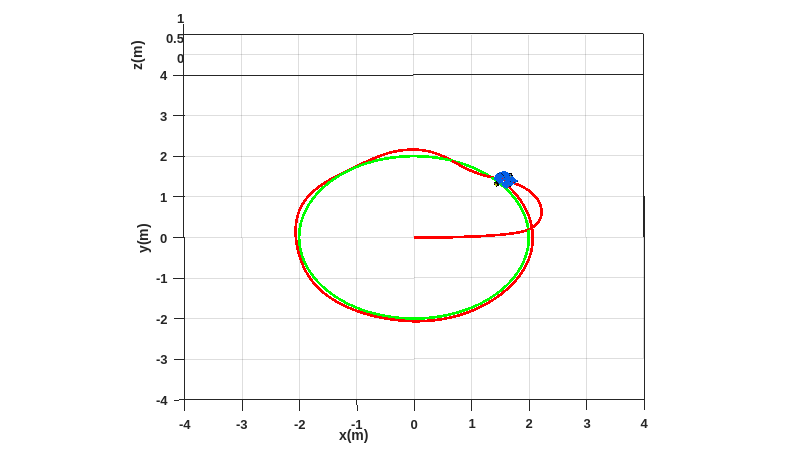

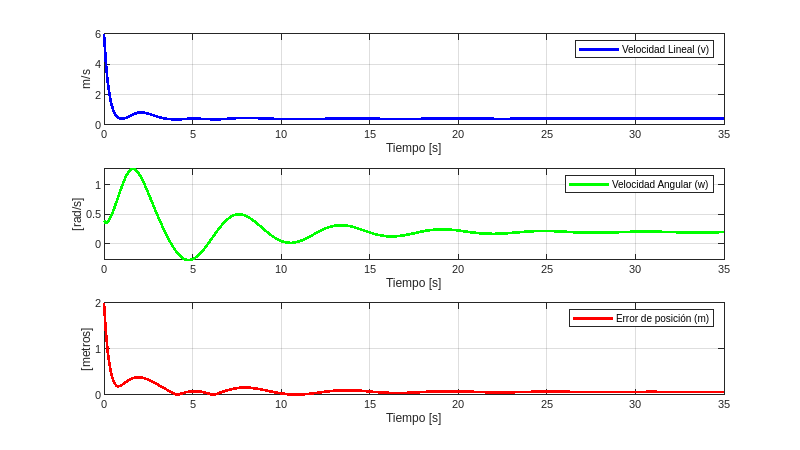

ts = 0.1;
t=0:ts:35;
K=[3 0; 0 3];

hxd=2*cos(0.2*t);  hyd=2*sin(0.2*t);
trayect(hxd, hyd, K, ts, t, -4, 4, -4, 4)

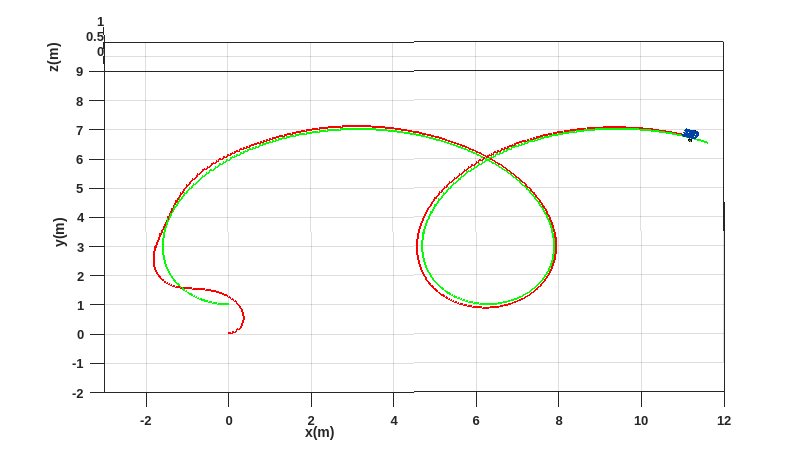

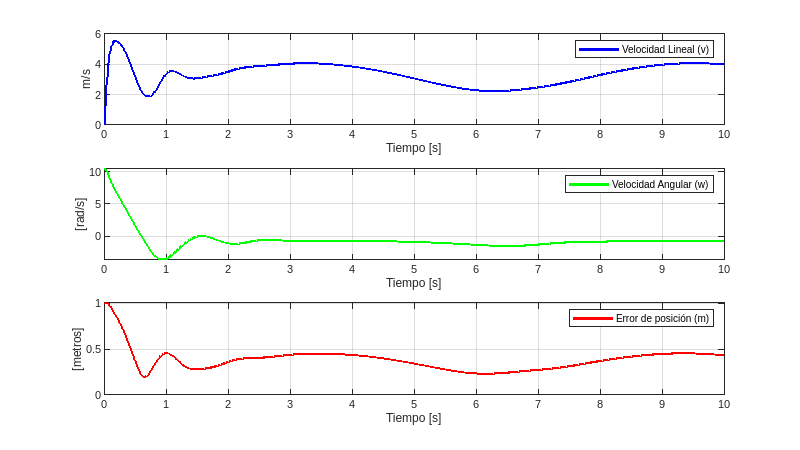

ts = 0.01;
t = 0:ts:10;
K = [10 0; 0 10];

hxd=t-3*sin(t);  hyd=4-3*cos(t);
trayect(hxd, hyd, K, ts, t, -3, 12, -2, 9)

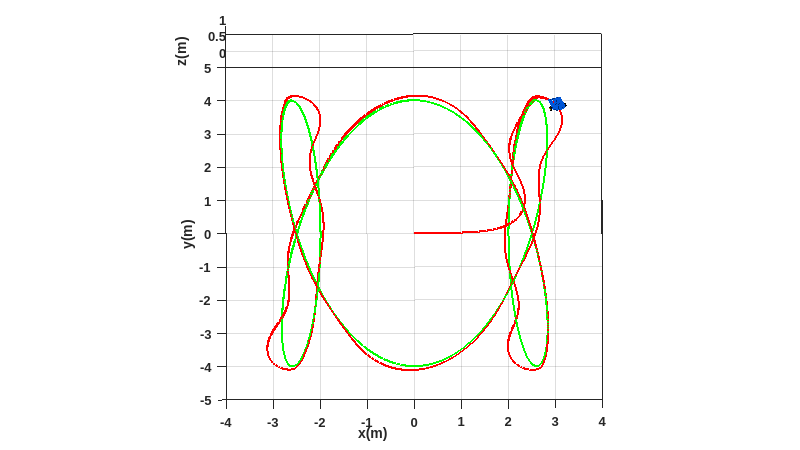

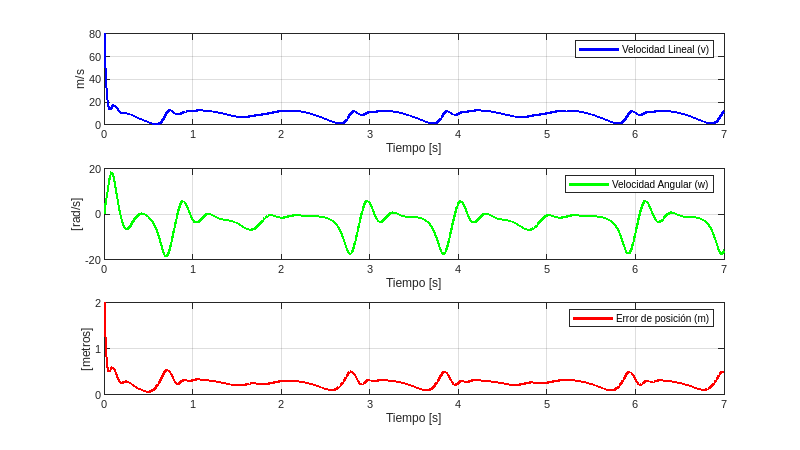

ts = 0.001;
t = 0:ts:7;
K = [40 0; 0 40];

hxd=3*cos(t)-cos(3*t);  hyd=4*sin(3*t);
trayect(hxd, hyd, K, ts, t, -4, 4, -5, 5)

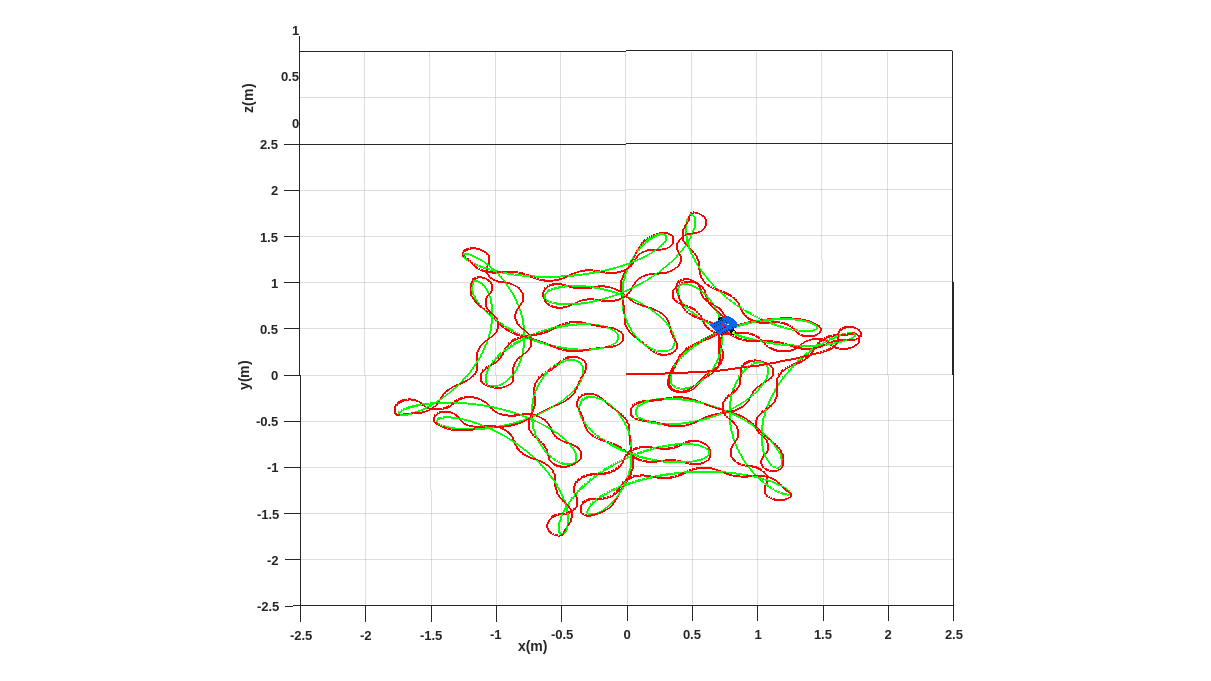

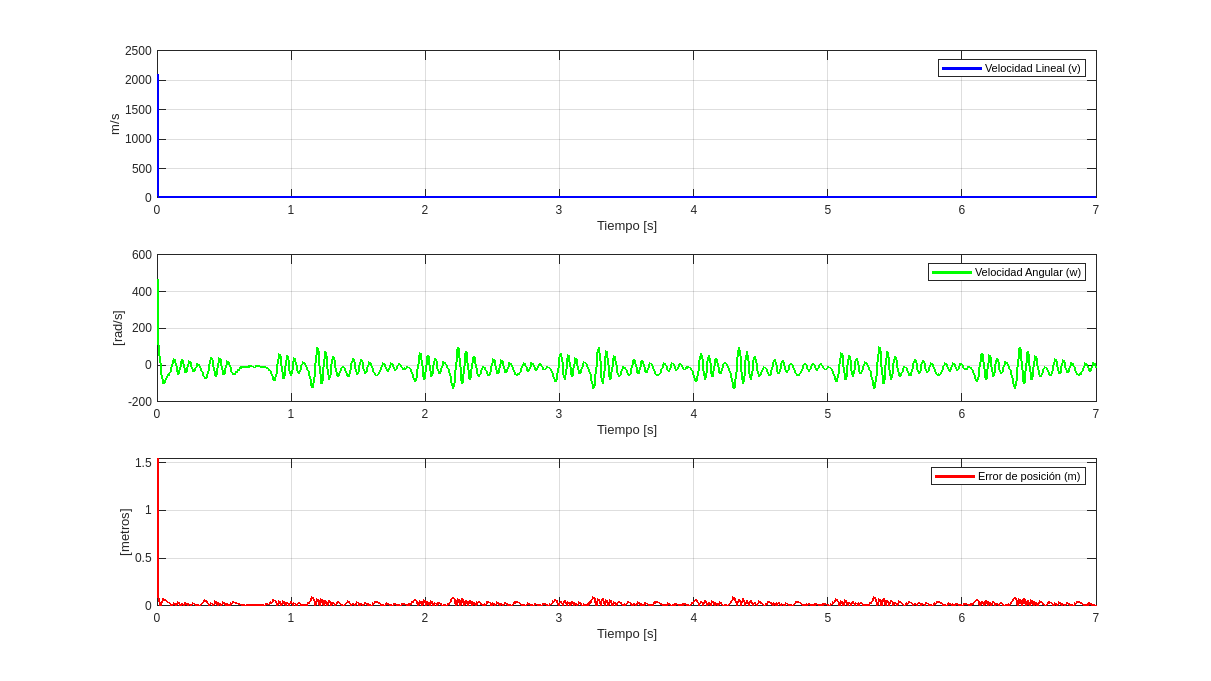

ts = 0.0001;
t = 0:ts:7;
K = [1400 0; 0 1400];

hxd=cos(t)+1/2*cos(7*t)+1/3*sin(17*t);  hyd=sin(t)+1/2*sin(7*t)+1/3*cos(17*t);
trayect(hxd, hyd, K, ts, t, -2.5, 2.5, -2.5, 2.5)

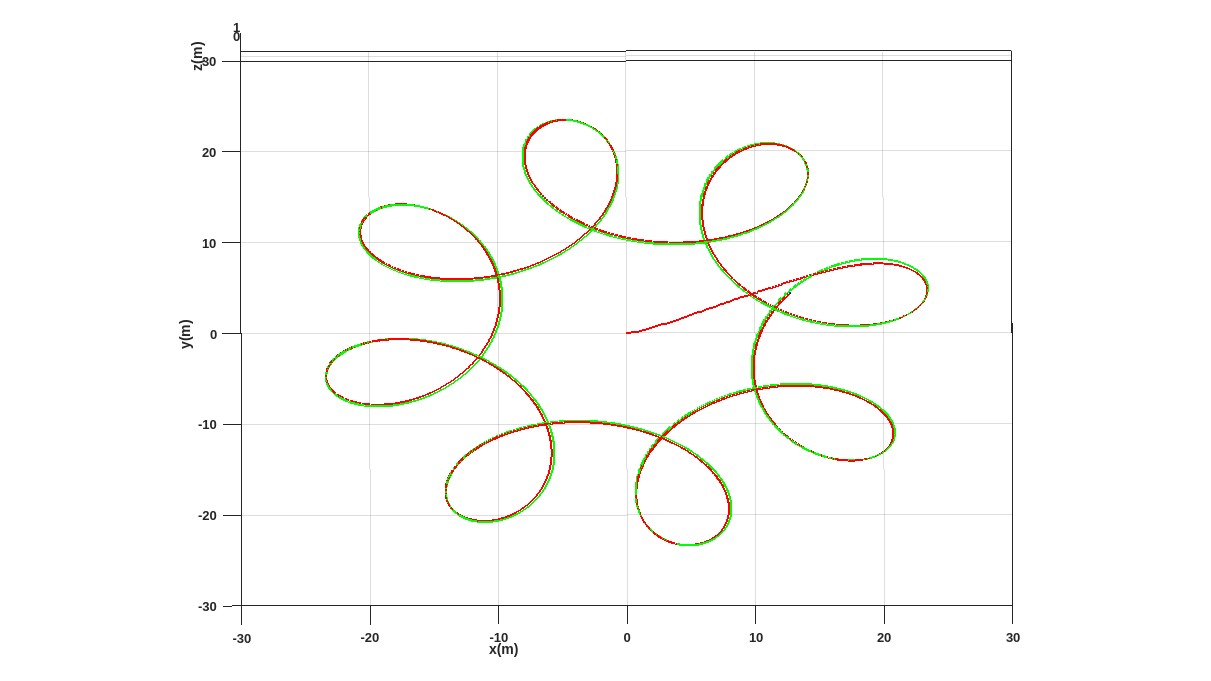

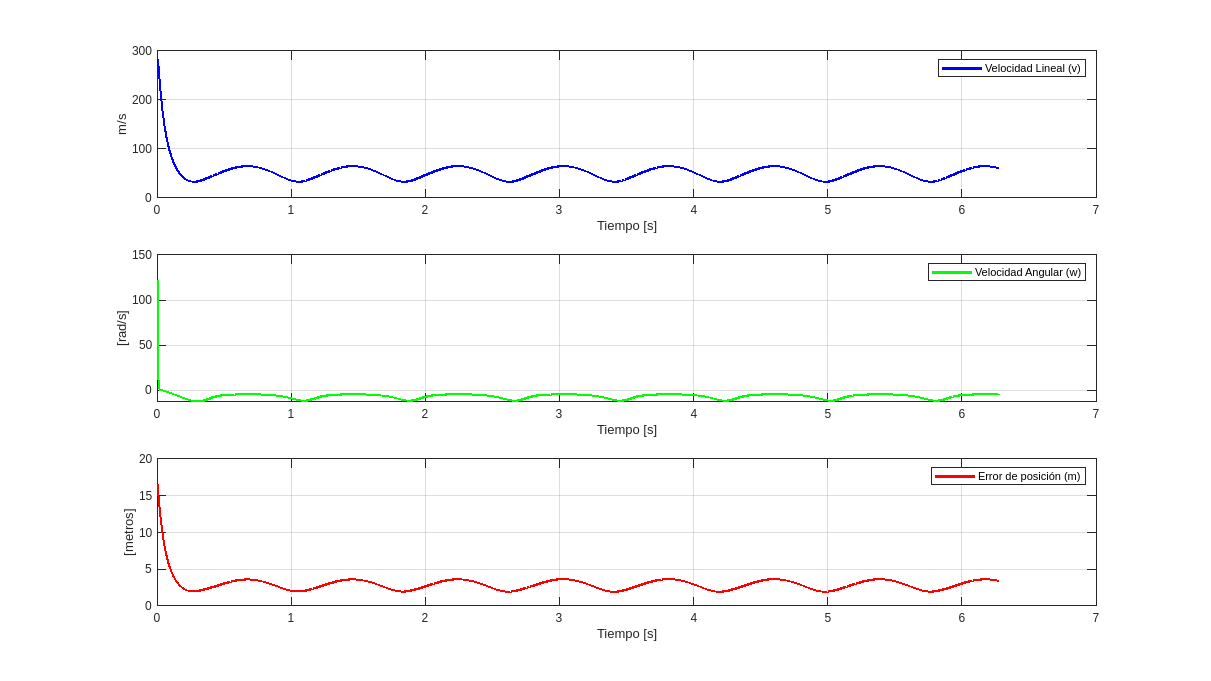

ts = 0.001;
t = 0:ts:2*pi;
K = [18 0; 0 18];

hxd=17*cos(t)+7*cos(17+7*t);  hyd=17*sin(t)-7*sin(17+7*t);
trayect(hxd, hyd, K, ts, t, -30, 30, -30, 30)

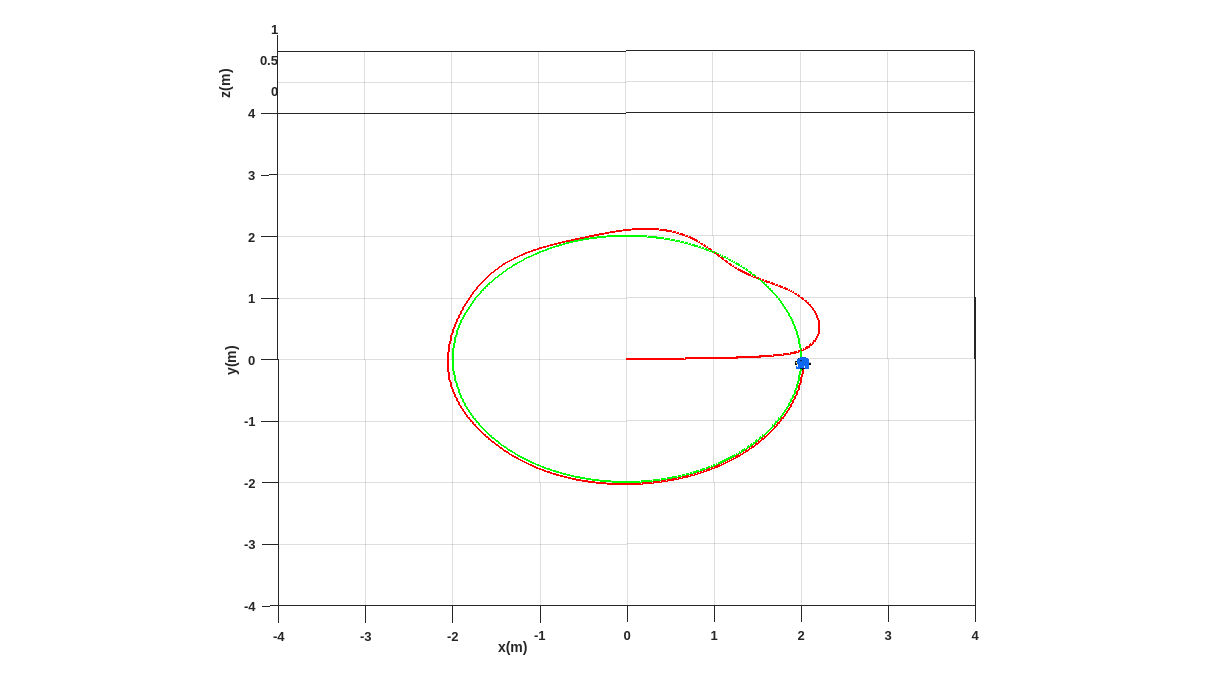

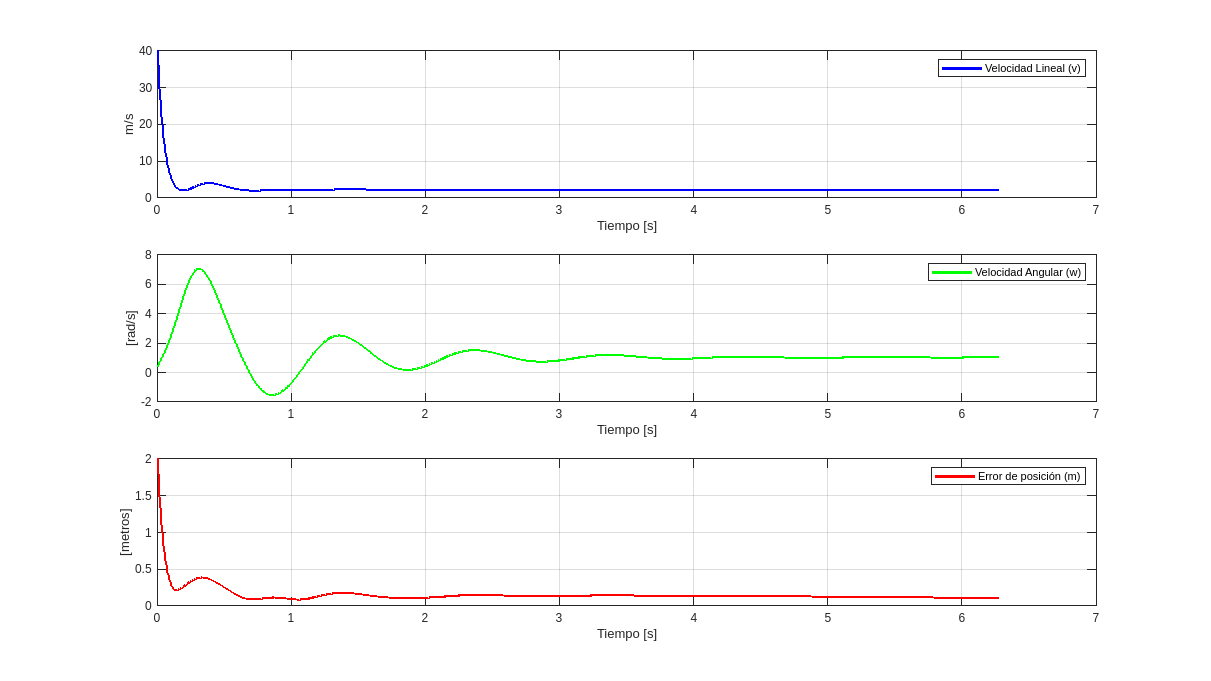

ts = 0.0001;
t = 0:ts:2*pi;
K = [20 0; 0 20];

hxd=2*cos(t);  hyd=2*sin(t);
trayect(hxd, hyd, K, ts, t, -4, 4, -4, 4)

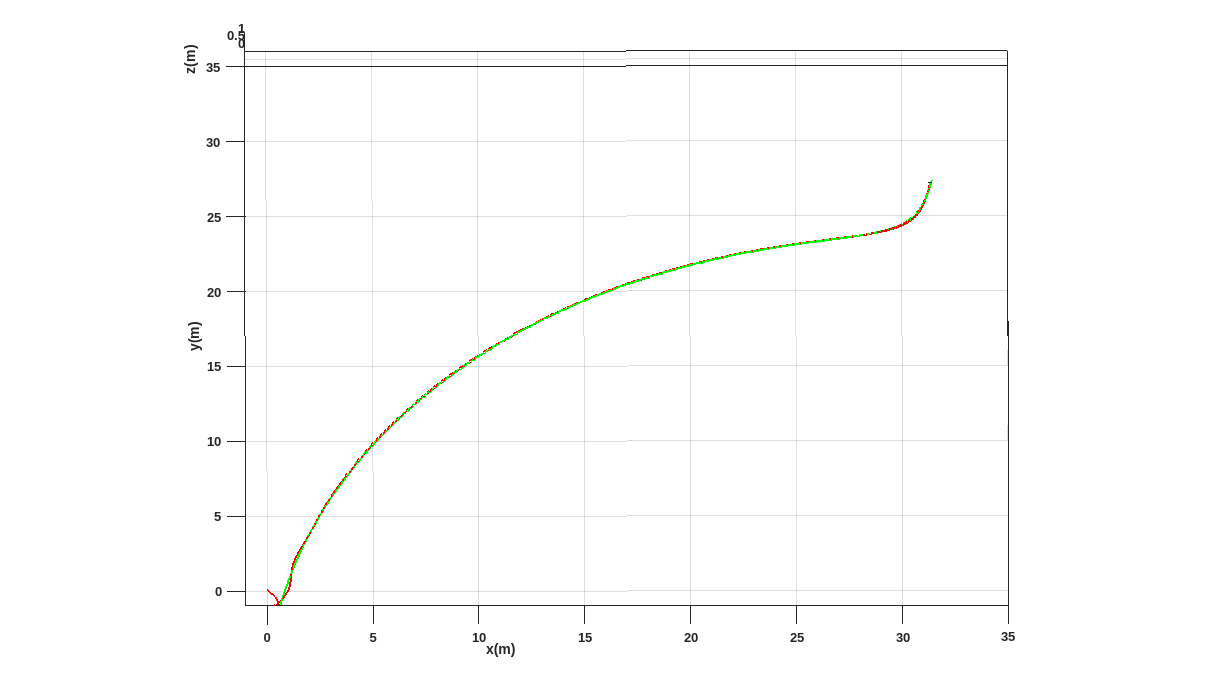

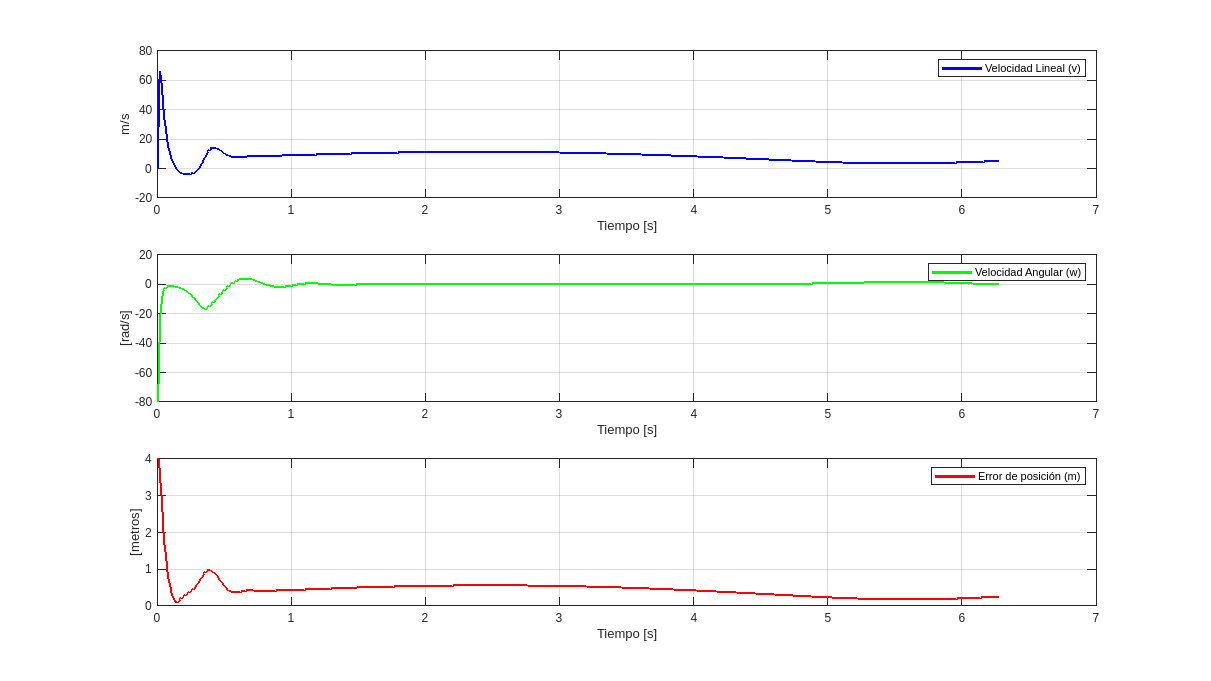

ts = 0.01;
t = 0:ts:2*pi;
K = [20 0; 0 20];

hxd=5*t-4*sin(t);  hyd=5*t-4*cos(t);
trayect(hxd, hyd, K, ts, t, -1, 35, -1, 35)

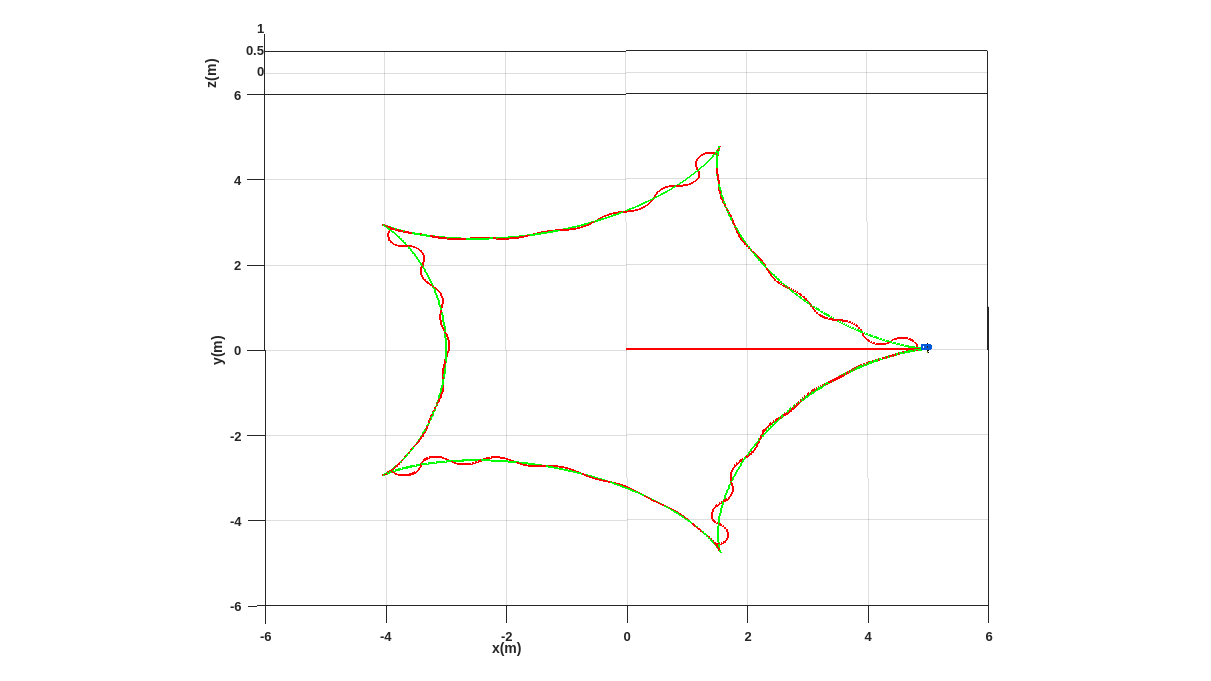

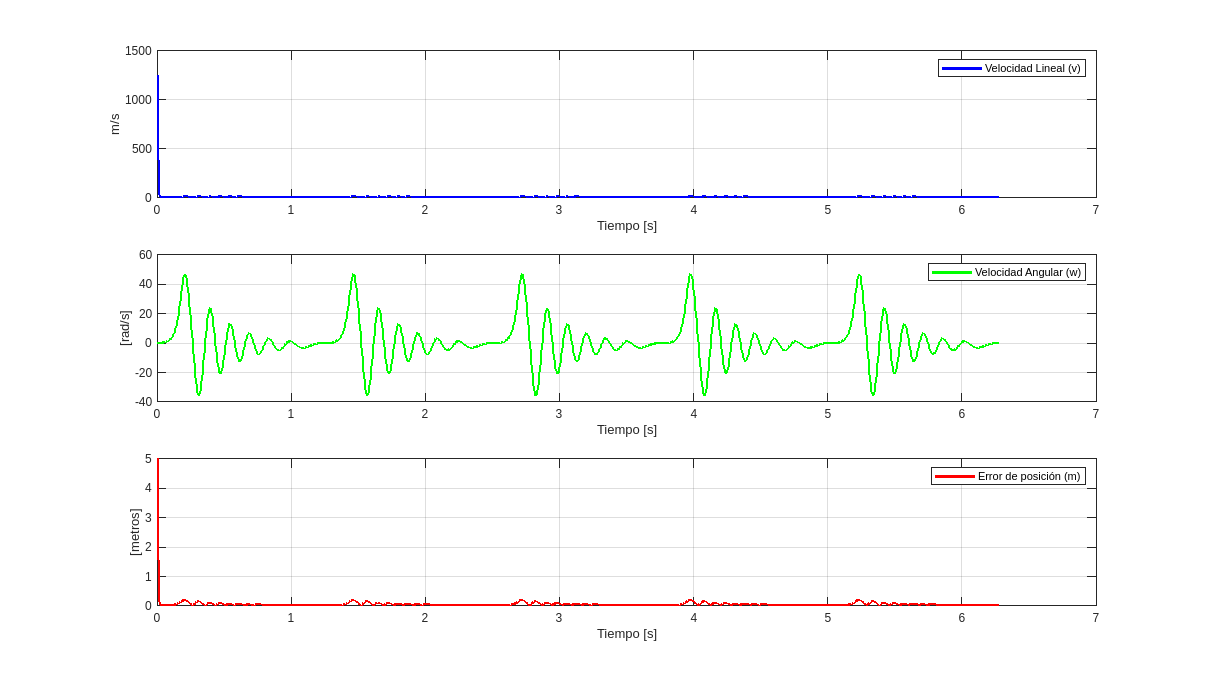

ts = 0.0001;
t = 0:ts:2*pi;
K = [250 0; 0 250];

hxd=4*cos(t)+cos(4*t);  hyd=4*sin(t)-sin(4*t);
trayect(hxd, hyd, K, ts, t, -6, 6, -6, 6)

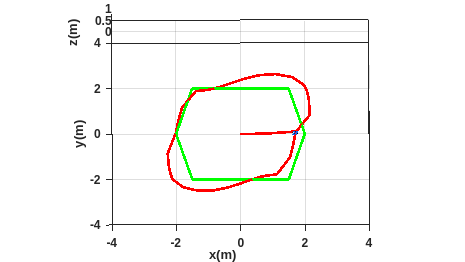

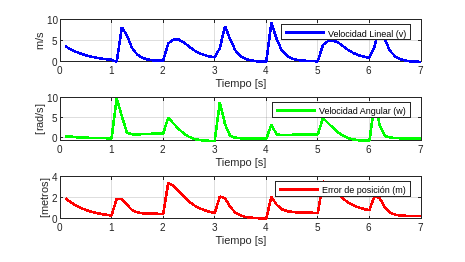

ts = 0.1;
t = ts:ts:7;
K = [1.9 0; 0 5];

hxd = [2*ones(1, 10) 1.5*ones(1, 10) -1.5*ones(1, 10), -2*ones(1, 10) -1.5*ones(1, 10) 1.5*ones(1, 10) 2*ones(1, 10)];
hyd = [0*ones(1, 10) 2*ones(1, 20) 0*ones(1, 10) -2*ones(1, 20) 0*ones(1, 10)];

trayect(hxd, hyd, K, ts, t, -4, 4, -4, 4)

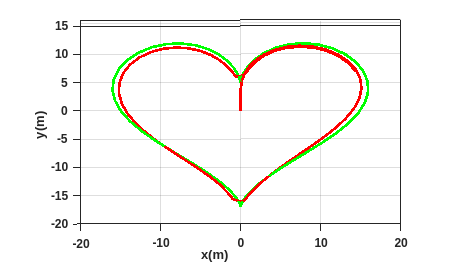

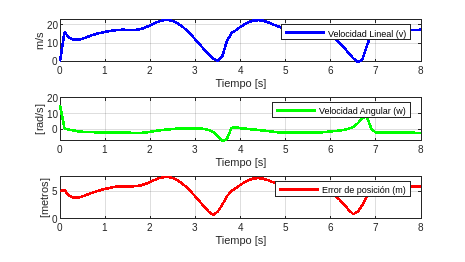

ts = 0.1;
t=0:ts:8;
K=[3 0; 0 3];

hxd=16*sin(t).^3;  
hyd=13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t);
trayect(hxd, hyd, K, ts, t, -20, 20, -20, 15)

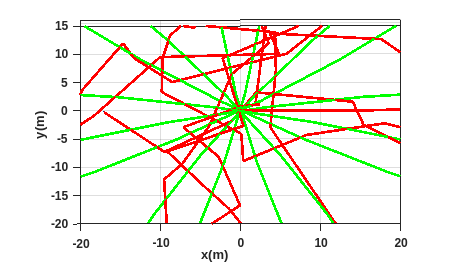

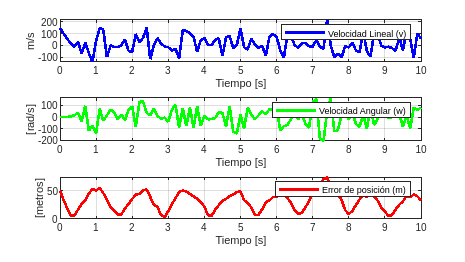

ts = 0.1;
t=0:ts:10;
K=[3 0; 0 3];

theta=0:pi/100:pi;
r=50*cos(8*theta);

hxd=r.*cos(theta);
hyd=r.*sin(theta);
%Imposible
trayect(hxd, hyd, K, ts, t, -20, 20, -20, 15)